clc;
clear all;
close all;

folders = ["results_lowest_clients" "results_50_50" "results_50_50_dup" "results_25_75" "results_25_75_dup" "results_75_25" "results_75_25_dup"];

load('Practica_Sist_Tec_Teleco.mat');

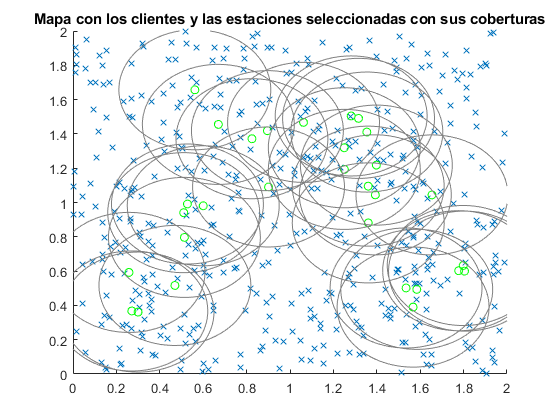

load('results_50_50_dup/best_sol.csv');
save_fig = figure(1);
%plot(bt(:,1), bt(:,2),'o');
hold on
plot(xp(:,1), xp(:,2),'x');
plot(best_sol(:,1), best_sol(:,2),'og')
viscircles(best_sol,ones(30,1)*0.350,"LineWidth",0.5,"Color",[0.5,0.5,0.5],"EnhanceVisibility",false);
xlim([0,2])
ylim([0,2])
title('Mapa con los clientes y las estaciones seleccionadas con sus coberturas')
hold off

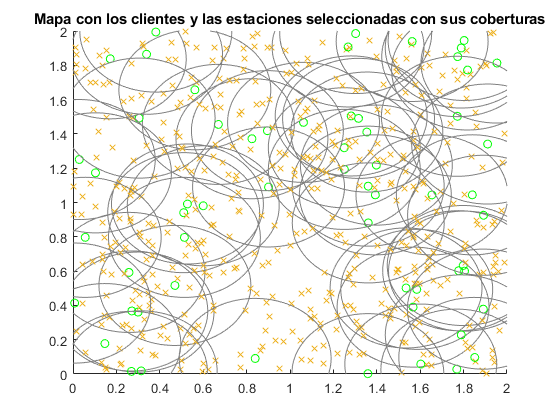

% Generate and save all coverage results
for i=1:length(folders)
    load(folders(i)+"/best_sol.csv")
    save_fig = figure(1);
    hold on
    plot(xp(:,1), xp(:,2),'x');
    plot(best_sol(:,1), best_sol(:,2),'og')
    viscircles(best_sol,ones(30,1)*0.350,"LineWidth",0.5,"Color",[0.5,0.5,0.5],"EnhanceVisibility",false);
    xlim([0,2])
    ylim([0,2])
    title('Mapa con los clientes y las estaciones seleccionadas con sus coberturas')
    hold off
    saveas(save_fig,folders(i)+"/sol_coverage.png")
    close(save_fig)
end